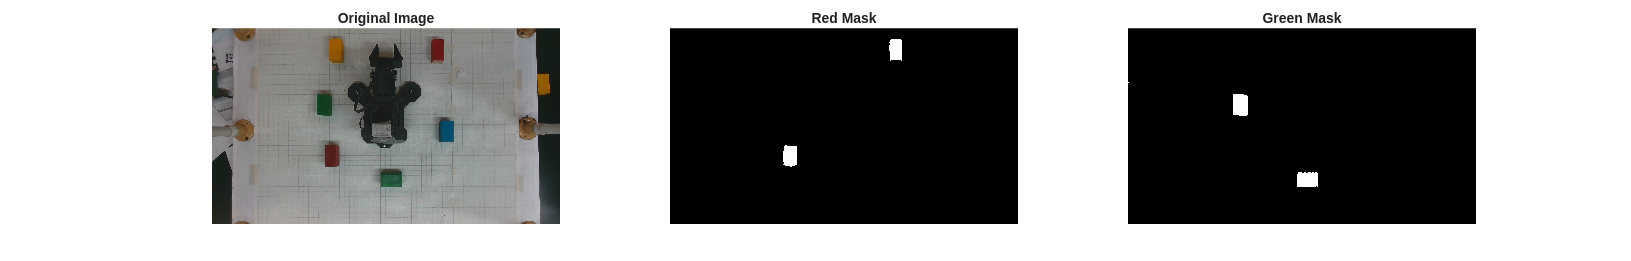

rgb = imread("Downloads/rgb_image_Color.png");

figure('Position', [100 100 2500 400]);

subplot(1,3,1)
imshow(rgb);
title('Original Image')

hsv_img = rgb2hsv(rgb);
[h, s, v] = imsplit(hsv_img);

% extracting red blocks
redMask = (h < 0.03 | h > 0.95) & s > 0.5 & v > 0.25;
subplot(1,3,2)
imshow(redMask);
title('Red Mask')

% extracting green blocks
greenMask = (h >= 0.25 & h <= 0.45) & (s >= 0.23) & (v >= 0.2);
subplot(1,3,3)
imshow(greenMask);
title('Green Mask')